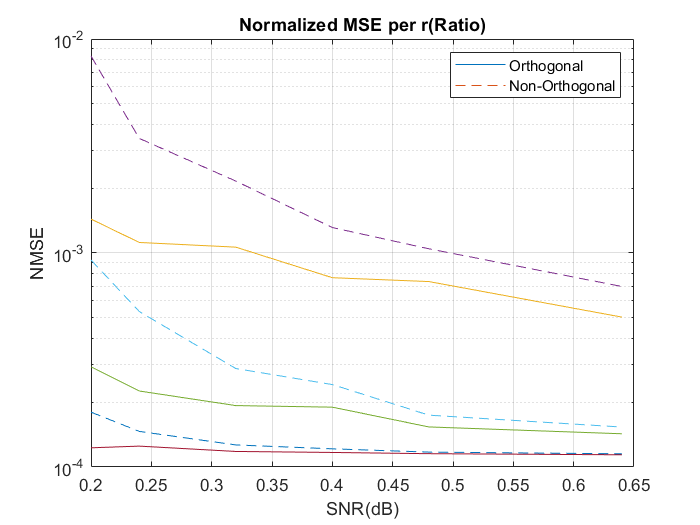

T_ch    = 200;                      % Coherence interval
SNR_dB  = (10:10:30);               % SNR in dB
T  = [40 48 64 80 96 128];          % Lenght of Pilot Sequence

figure(1)
for i=1:length(SNR_dB)
semilogy((T/T_ch),Orth(i,:),...
         (T/T_ch),North(i,:),'--')
     hold on
end
grid on
legend('Orthogonal','Non-Orthogonal')
xlabel('SNR(dB)')
ylabel('NMSE')
title('Normalized MSE per r(Ratio)')